# Deep Learning with MATLAB

## Deep Learning Toolbox

[https://www.mathworks.com/products/statistics.html](https://www.mathworks.com/products/deep-learning.html)

Deep Learning Toolbox™ provides a framework for designing and implementing deep neural networks with algorithms, pretrained models, and apps. 

- use convolutional neural networks (ConvNets, CNNs) and long short-term memory (LSTM) networks to perform classification and regression on image, time-series, and text data

- build network architectures such as generative adversarial networks (GANs) and Siamese networks using automatic differentiation, custom training loops, and shared weights

- design, analyze, and train networks graphically with the Deep Network Designer app

- exchange models with TensorFlow™ and PyTorch through the ONNX format and import models from TensorFlow-Keras and Caffe

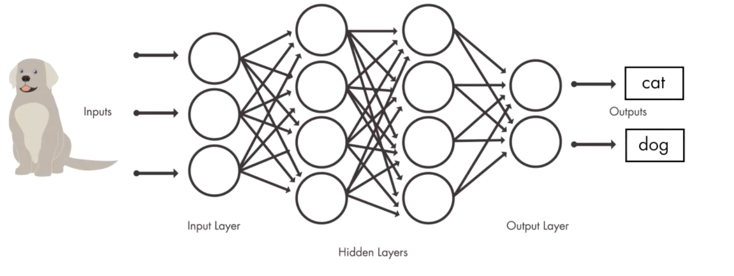

[**Deep Learning Onramp**](https://matlabacademy.mathworks.com/R2020b/portal.html?course=deeplearning) is a nice introduction course.

### Use Pretrained Model

***Deep Learning Toolbox Model for GoogLeNet Network ***

*Install the package use the Add-On Explorer.*

GoogLeNet is a pretrained model that has been trained on a subset of the ImageNet database which is used in the ImageNet Large-Scale Visual Recognition Challenge (ILSVRC). The model is trained on more than a million images, has 144 layers, and can classify images into 1000 object categories (e.g. keyboard, mouse, pencil, and many animals). 

Get the layers from GoogLeNet.

net = googlenet;

Display layers of GoogLeNet

net.Layers

ans =   144x1 Layer array with layers:

     1   'data'                           Image Input                   224x224x3 images with 'zerocenter' normalization
     2   'conv1-7x7_s2'                   Convolution                   64 7x7x3 convolutions with stride [2  2] and padding [3  3  3  3]
     3   'conv1-relu_7x7'                 ReLU                          ReLU
     4   'pool1-3x3_s2'                   Max Pooling                   3x3 max pooling with stride [2  2] and padding [0  1  0  1]
     5   'pool1-norm1'                    Cross Channel Normalization   cross channel normalization with 5 channels per element
     6   'conv2-3x3_reduce'               Convolution                   64 1x1x64 convolutions with stride [1  1] and padding [0  0  0  0]
     7   'conv2-relu_3x3_reduce'          ReLU                          ReLU
     8   'conv2-3x3'                      Convolution                  

View network architecture

analyzeNetwork(net)

### **Extracting and Visualizing Activations**

Load an image

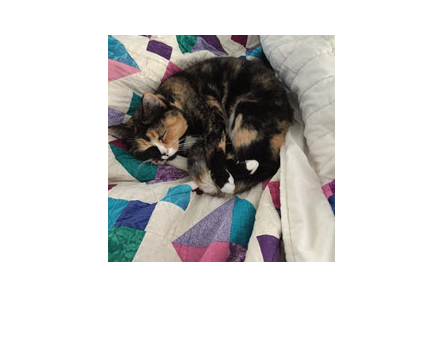

img = imread("data/cat.jpg");
imshow(img)

Extract features from an input image using a CNN with the `activations` function.

`Y = activations(net, X, layerOut) `returns network activations for a specific layer using the network `net` and the data `X`. Network activations are computed by forward propagating the input X through the network up to the specified layer. 

actvn = activations(net,img,"conv1-7x7_s2");

Normalize the activations using the function `mat2gray` and display multiple images together using the `montage` function 

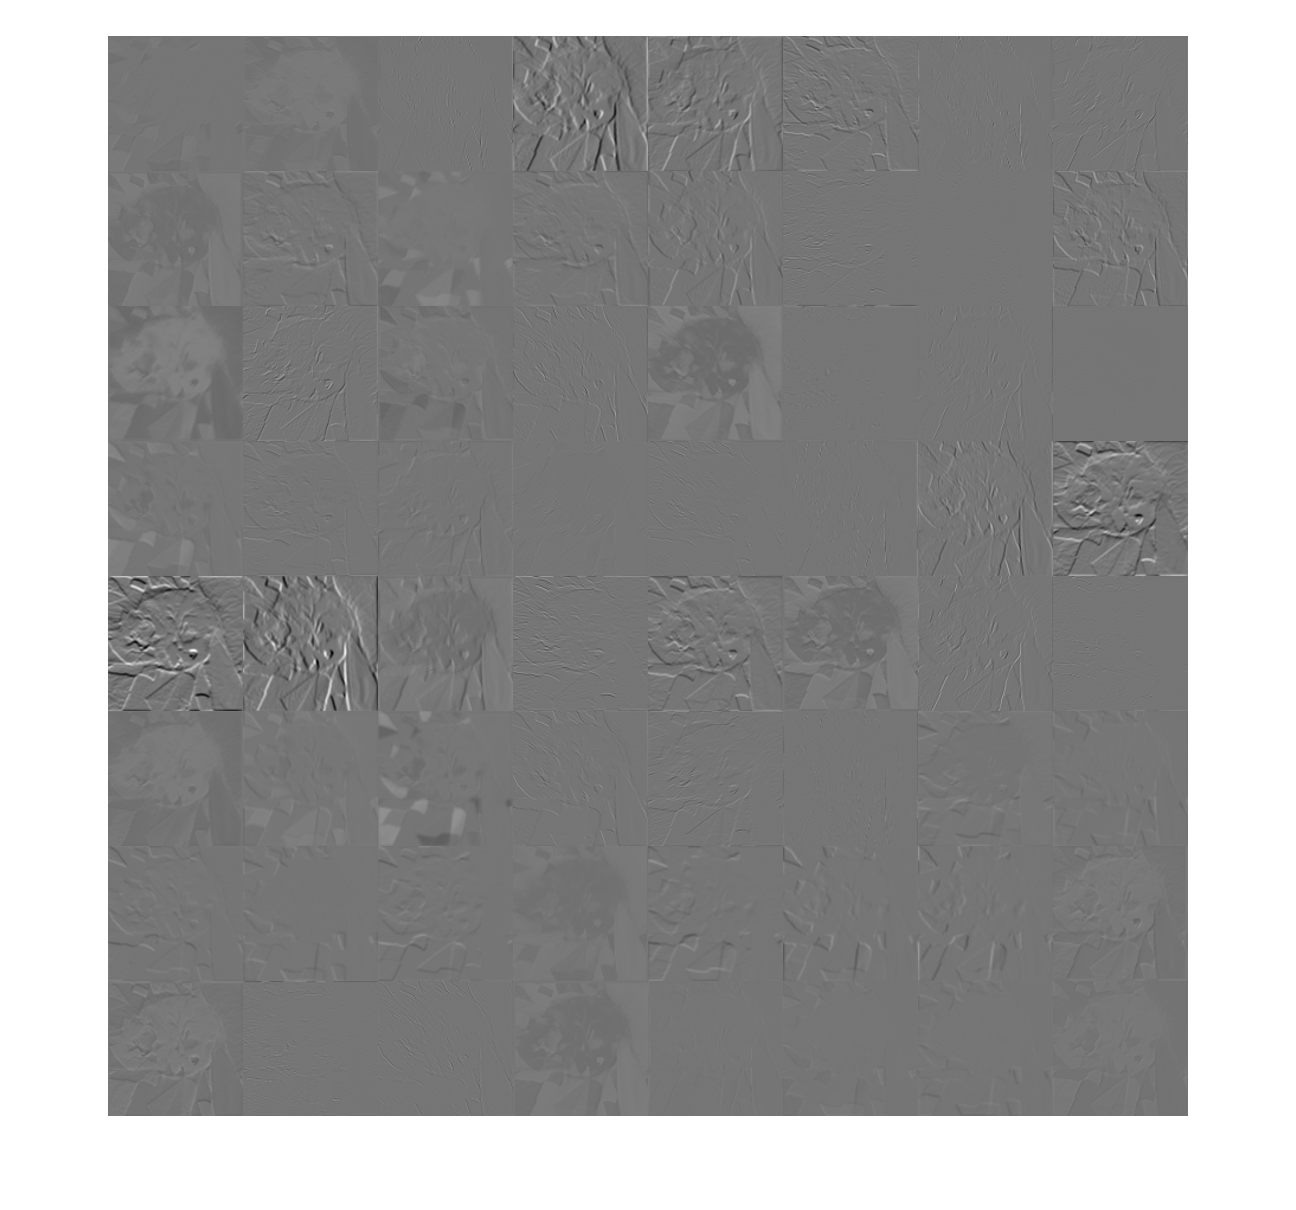

montage(mat2gray(actvn))

### Demo: Flower Image Classification

#### Get training images

flowerds = imageDatastore("data/Flowers",...
    "IncludeSubfolders",true,"LabelSource","foldernames");

Split into training and testing sets

[trainImgs,testImgs] = splitEachLabel(flowerds,0.7);

Determine the number of flower species

numClasses = numel(categories(flowerds.Labels))

numClasses = 7

Visualize specific image

img = readimage(flowerds,2);
disp(flowerds.Labels(2))

     buttercup 



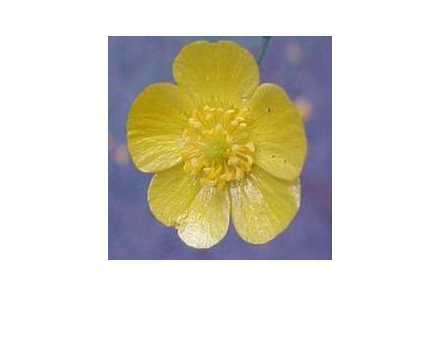

imshow(img)

img = readimage(flowerds,100);
disp(flowerds.Labels(100))

     crocus 



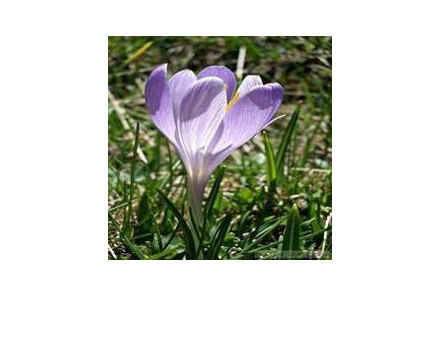

imshow(img)

### Create a network by modifying GoogLeNet

Modify the classification and output layers

lgraph = layerGraph(net)

lgraph =   LayerGraph with properties:

         Layers: [144×1 nnet.cnn.layer.Layer]
    Connections: [170×2 table]


lgraph.Layers(end-2:end)

ans =   3x1 Layer array with layers:

     1   'loss3-classifier'   Fully Connected         1000 fully connected layer
     2   'prob'               Softmax                 softmax
     3   'output'             Classification Output   crossentropyex with 'tench' and 999 other classes

newFc = fullyConnectedLayer(numClasses,"Name","new_fc")

newFc =   FullyConnectedLayer with properties:

          Name: 'new_fc'

   Hyperparameters
     InputSize: 'auto'
    OutputSize: 7

   Learnable Parameters
       Weights: []
          Bias: []

  Show all properties


lgraph = replaceLayer(lgraph,"loss3-classifier",newFc)

lgraph =   LayerGraph with properties:

         Layers: [144×1 nnet.cnn.layer.Layer]
    Connections: [170×2 table]


newOut = classificationLayer("Name","new_out")

newOut =   ClassificationOutputLayer with properties:

            Name: 'new_out'
         Classes: 'auto'
      OutputSize: 'auto'

   Hyperparameters
    LossFunction: 'crossentropyex'


lgraph = replaceLayer(lgraph,"output",newOut)

lgraph =   LayerGraph with properties:

         Layers: [144×1 nnet.cnn.layer.Layer]
    Connections: [170×2 table]


lgraph.Layers(end-2:end)

ans =   3x1 Layer array with layers:

     1   'new_fc'    Fully Connected         7 fully connected layer
     2   'prob'      Softmax                 softmax
     3   'new_out'   Classification Output   crossentropyex

Plot neural network layer graph

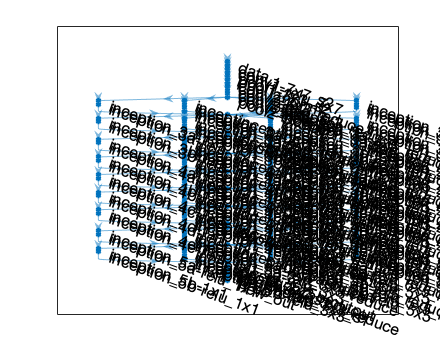

plot(lgraph)

#### Set training algorithm options

Lower the learning rate for transfer learning.

Set the number of epochs and mini-batch size.

- An **iteration** is one step taken in the **gradient descent algorithm** towards minimizing the loss function using a mini-batch. 

- An **epoch** is the full pass of the training algorithm over the entire training set

- Iterations per epoch = Number of training samples / Mini-batch size 

- Number of iterations = Iterations per epoch * Number of epochs

options = trainingOptions("sgdm","InitialLearnRate", 0.01,...
    'MiniBatchSize',100,'MaxEpochs',5,'Plots','training-progress');

#### Perform training

[flowernet,info] = trainNetwork(trainImgs, lgraph, options);

Training on single CPU.


Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:42 |       19.00% |       3.8853 |          0.0100 |


#### Use the trained network to classify test images

testpreds = classify(flowernet,testImgs);

#### Evaluate the results

Calculate the accuracy

nnz(testpreds == testImgs.Labels)/numel(testpreds)

Visualize the confusion matrix

confucsionchart(testImgs.Labels,testpreds);

clear; clc

### **Creating Network Architectures from Scratch**

### **Demo: Classify Musical Instruments**

The data set contains spectrograms of 14 musical instruments. It was obtained from from the University of Iowa Electronic Music Studio ([http://theremin.music.uiowa.edu/](http://theremin.music.uiowa.edu/)) and available via MATLAB online course resources. 

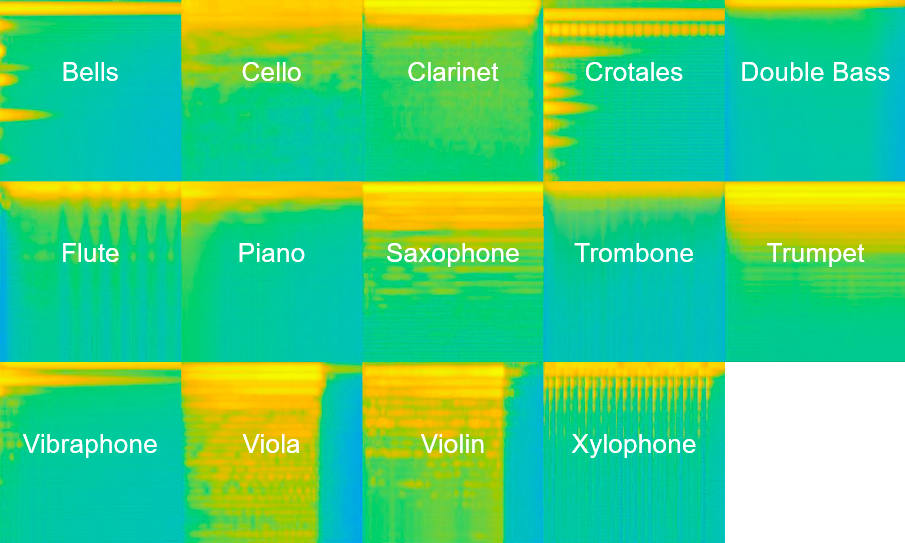

#### Load and split data

The images are stored in the folder `Spectrograms`. The data for each instrument is separated in subfolders, labelled by the folder name.

Split the data so that 80% of the images are used for training, 10% are used for validation, and the rest are used for testing. If changing the image size, make augmented image datastores.

imds = imageDatastore("data/Spectrograms",...
    "IncludeSubfolders",true,"LabelSource","foldernames");
[trainImgs,valImgs,testImgs] = splitEachLabel(imds,0.8,0.1,0.1,"randomized");

trainDs = augmentedImageDatastore([100 100],trainImgs);
valDs = augmentedImageDatastore([100 100],valImgs);
testDs = augmentedImageDatastore([100 100],testImgs);

#### Create the series architecture from the documentation

You can find the example that uses this architecture in the documentation here: [Speech Recognition](https://www.mathworks.com/help/nnet/examples/deep-learning-speech-recognition.html#d119e1562)

The images are sized `[100 100 3]`.

numClasses = numel(categories(trainImgs.Labels))

numClasses = 14

dropoutProb = 0.2;
layers = [
    imageInputLayer([100 100 3])

    % A conv layer with 16 filters that have a height and width of 3 
    % Default strid is [1 1],the step size for traversing the input
    % Padding is set so that the output size is ceil(inputSize/stride).
    convolution2dLayer(3,16,"Padding","same")
    batchNormalizationLayer
    reluLayer

    % A max pooling layer with non-overlapping pooling regions,
    % which downsamples by a factor of 2.
    maxPooling2dLayer(2,"Stride",2)

    convolution2dLayer(3,32,"Padding","same")
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(2,"Stride",2,"Padding",[0,1])

    dropoutLayer(dropoutProb)
    convolution2dLayer(3,64,"Padding","same")
    batchNormalizationLayer
    reluLayer

    dropoutLayer(dropoutProb)
    convolution2dLayer(3,64,"Padding","same")
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(2,"Stride",2,"Padding",[0,1])

    dropoutLayer(dropoutProb)
    convolution2dLayer(3,64,"Padding","same")
    batchNormalizationLayer
    reluLayer

    dropoutLayer(dropoutProb)
    convolution2dLayer(3,64,"Padding","same")
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer([1 13])

    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer];

layers

layers =   30x1 Layer array with layers:

     1   ''   Image Input             100x100x3 images with 'zerocenter' normalization
     2   ''   Convolution             16 3x3 convolutions with stride [1  1] and padding 'same'
     3   ''   Batch Normalization     Batch normalization
     4   ''   ReLU                    ReLU
     5   ''   Max Pooling             2x2 max pooling with stride [2  2] and padding [0  0  0  0]
     6   ''   Convolution             32 3x3 convolutions with stride [1  1] and padding 'same'
     7   ''   Batch Normalization     Batch normalization
     8   ''   ReLU                    ReLU
     9   ''   Max Pooling             2x2 max pooling with stride [2  2] and padding [0  0  1  1]
    10   ''   Dropout                 20% dropout
    11   ''   Convolution             64 3x3 convolutions with stride [1  1] and padding 'same'
    12   ''   Batch Normalization     Batch normalization


#### Train the network

Set the training options and train the network.

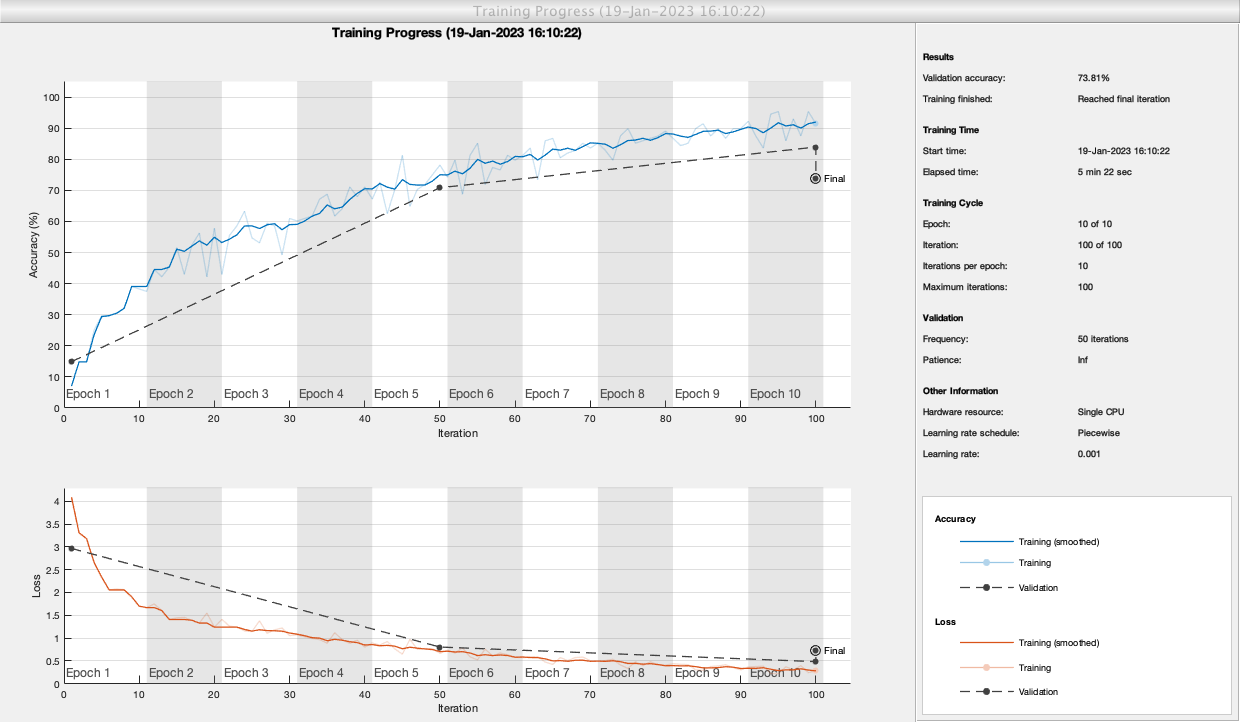

Training on single CPU.


Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:07 |        7.03% |       14.88% |       4.0869 |       2.9642 |          0.0010 |
|       5 |          50 |       00:02:51 |       78.12% |       70.83% |       0.6654 |       0.8026 |          0.0010 |
|      10 |         100 |       00:05:22 |       91.41% |       83.93% |       0.2811 |       0.4825 |          0.0010 |
|=================================================================================================================

options = trainingOptions("adam", ...
    'MaxEpochs',10,...
    "Plots","training-progress", ...
    "ValidationData",valDs, ...
    "LearnRateSchedule","piecewise", ...
    "LearnRateDropPeriod",15);

scratchNet = trainNetwork(trainDs,layers,options);

#### Evaluate network

Calculate the accuracy on the test dataset.

testPred = classify(scratchNet,testDs);
nnz(testPred == testImgs.Labels)/numel(testImgs.Labels)

ans = 0.7784

Plot confusion matrix

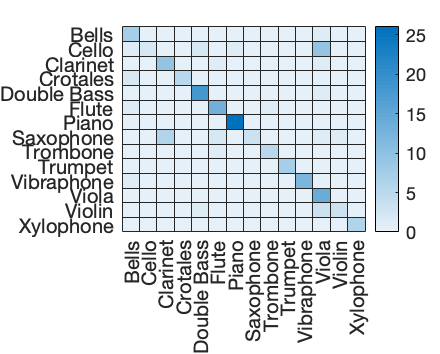

ans =   HeatmapChart with properties:

        XData: {14×1 cell}
        YData: {14×1 cell}
    ColorData: [14×14 double]

  Show all properties


[cmap,clabel] = confusionmat(testImgs.Labels,testPred);
heatmap(clabel,clabel,cmap)

### (Optional) Practice

Try write your own neural network architecture to classify the instruments.

clear; clc

### LSTM (Long Short-Term Memory) Network

### Demo: Time Series Forecasting for Chickenpox Cases

#### Load, visualize, and process data

Load the months and values of the number of cases of chickenpox (without using datastore).

data = chickenpox_dataset;
data = [data{:}];

figure
plot(data)
xlabel("Month")
ylabel("Cases")
title("Monthly Cases of Chickenpox")

Split into training and test sets at a 80%-20% ratio.

numTimeStepsTrain = floor(0.8*numel(data));

dataTrain = data(1:numTimeStepsTrain+1);
dataTest = data(numTimeStepsTrain+1:end);

Standardize data.

mu = mean(dataTrain);
sig = std(dataTrain);
dataTrainStandardized = (dataTrain - mu) / sig;

Speicify repsonses (sequence values shifted by one time step).

XTrain = dataTrainStandardized(1:end-1);
YTrain = dataTrainStandardized(2:end);

#### Create an LSTM regression network

numFeatures = 1;
numResponses = 1;
numHiddenUnits = 200;

lstmLayers = [ ...
    sequenceInputLayer(numFeatures)
    lstmLayer(numHiddenUnits)
    fullyConnectedLayer(numResponses)
    regressionLayer];
lstmLayers

Specify training options.

options = trainingOptions('adam', ...
    'MaxEpochs',250, ...
    'GradientThreshold',1, ...
    'InitialLearnRate',0.005, ...
    'LearnRateSchedule','piecewise', ...
    'LearnRateDropPeriod',125, ...
    'LearnRateDropFactor',0.2, ...
    'Verbose',0, ...
    'Plots','training-progress');

Train the network.

lstmNet = trainNetwork(XTrain,YTrain,lstmLayers,options);

#### Make predictions (forcasting)

dataTestStandardized = (dataTest - mu) / sig;
XTest = dataTestStandardized(1:end-1);
% initialize the network state by predicting on the training data 
lstmNet = predictAndUpdateState(lstmNet,XTrain);
% start from the last time step of the training response
[lstmNet,YPred] = predictAndUpdateState(lstmNet,YTrain(numel(YTrain)));
% loop over the remaining predictions
for i = 2:numel(XTest)
    [lstmNet,YPred(:,i)] = predictAndUpdateState(lstmNet,YPred(:,i-1),'ExecutionEnvironment','cpu');
end

Evaluate performances.

YPred = sig*YPred + mu;
YTest = dataTest(2:end);
rmse = sqrt(mean((YPred-YTest).^2))

figure
subplot(2,1,1)
plot(YTest)
hold on
plot(YPred,'.-')
hold off
legend(["Observed" "Forecast"])
ylabel("Cases")
title("Forecast")

subplot(2,1,2)
stem(YPred - YTest)
xlabel("Month")
ylabel("Error")
title("RMSE = " + rmse)